folder = "D:\Whale Data\Raw Audio Data\CaseyIslands2017";
dsname = "CaseyIslands2017";

fb = load(folder + "\scattering\filterbank.mat").fb;
sizef = numel(fb.filterBanks(1).lambdas);
scatfs = fb.filterBanks(1).getSSamplingFreq()

scatfs = 6.2500

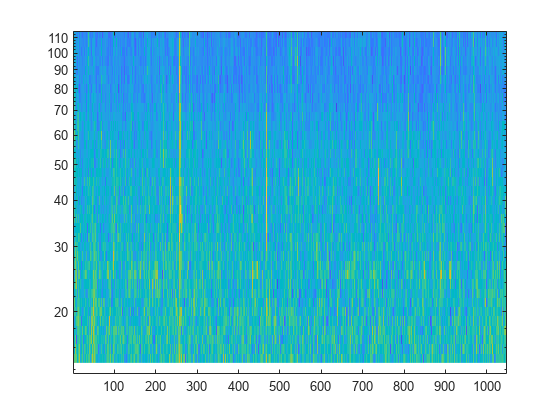

% s = load(folder + "\scattering\2017_02_05_15_04_22_144.mat").s;
% s = load(folder + "\scattering\2017_02_07_10_26_12_864.mat").s;
% s = load(folder + "\scattering\2016_12_16_08_08_44_288.mat").s;
s = load(folder + "\scattering\2016_12_16_08_00_00_000.mat").s;
s1 = s(1:sizef, :).^2;
t = (1:size(s, 2))/scatfs;

figure
Tools.plotTF(s1, fb.filterBanks(1).fc, true, true, t);

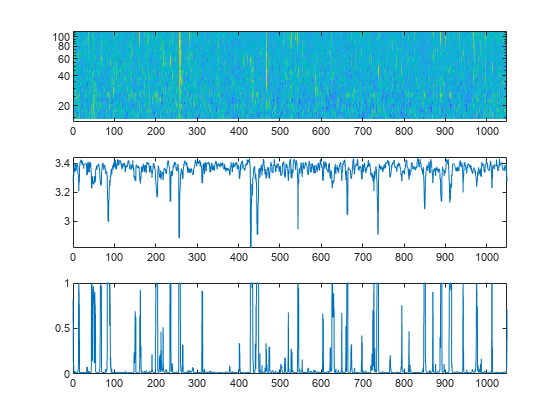

s1smooth = smoothdata(s1, 1, "movmedian", 5);
snoise = prctile(s1smooth, 50, 2);
sw = s1./snoise;

M = floor(1.5 * scatfs)*2 + 1;
% M = 1;
segmm = SEGMM(M);
segmm.detect(sw);

figure
ax1 = subplot(311);
Tools.plotTF(log(sw), fb.filterBanks(1).fc, true, false, t);
ax2 = subplot(312);
plot(t, segmm.H);
ax3 = subplot(313);
plot(t, segmm.probs);
linkaxes([ax1, ax2], 'x');
linkaxes([ax1, ax3], 'x');
xlim([0, max(t)])

annotations = load(folder + "\annotations\annotations.mat").annotationTable;
annfiles = unique(annotations.File)

annfiles = 460×1 string array
    "2016_12_16_08_00_00_000.wav"
    "2016_12_16_08_17_28_576.wav"
    "2016_12_16_08_34_57_152.wav"
    "2016_12_16_08_52_25_728.wav"
    "2016_12_18_03_00_00_000.wav"
    "2016_12_18_03_17_28_576.wav"
    "2016_12_18_03_34_57_152.wav"
    "2016_12_18_03_52_25_728.wav"
    "2016_12_19_21_00_00_000.wav"
    "2016_12_19_21_17_28_576.wav"
    "2016_12_23_10_00_00_000.wav"
    "2016_12_23_10_17_28_576.wav"
    "2016_12_23_10_52_25_728.wav"
    "2016_12_25_05_00_00_000.wav"
    "2016_12_25_05_17_28_576.wav"
    "2016_12_25_05_34_57_152.wav"
    "2016_12_25_05_52_25_728.wav"
    "2016_12_26_23_00_00_000.wav"
    "2016_12_26_23_17_28_576.wav"
    "2016_12_26_23_34_57_152.wav"
    "2016_12_26_23_52_25_728.wav"
    "2016_12_28_18_00_00_000.wav"
    "2016_12_30_12_52_25_728.wav"
    "2017_01_01_06_17_28_576.wav"
    "2017_01_04_19_34_57_152.wav"
    "2017_01_06_14_00_00_000.wav"
    "2017_01_06_14_17_28_576.wav"
    "2017_01_06_14_34_57_152.wav"
    "2017_01_06_14

exfile = annfiles(58)

exfile = "2017_01_31_08_17_28_576.wav"

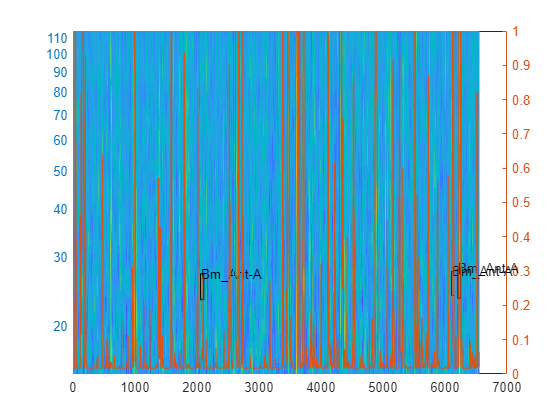

% exfile = "2016_12_16_08_00_00_000.wav";
exfilescat = replace(exfile, ".wav", ".mat");
% Q = [16, 4];
% T = 1.5;
% flow = 15;
% fhigh = 120;
% fb = Scattering(Q, T, 250, AudioDataConverter.L, flow, fhigh, 2);
% x = audioread(folder + "\" + exfile);
% s = fb.scattering(x);
% t = (1:size(s, 2))/fb.filterBanks(1).getSSamplingFreq();
% s1 = s(1:numel(fb.filterBanks(1).lambdas), :);
exann = annotations(annotations.File == exfile, :);
% exann = detectors(9).annotations;
s = load(folder + "\scattering\" + exfilescat).s;
s = s.^2;
t = (1:size(s, 2))/fb.filterBanks(1).getSSamplingFreq();
s1 = s(1:numel(fb.filterBanks(1).lambdas), :);

s1smooth = smoothdata(s1, 1, "movmedian", 9);
% s1smooth = smoothdata(s1smooth, 2, "movmedian", floor(scatfs*10));
snoise = smoothdata(s1smooth, 2, "movmedian", floor(scatfs*60));
sw = s1./snoise;

M = floor(1.5 * scatfs)*2 + 1;
% M = 1;
clear segmm
segmm = SEGMM(M);
segmm.detect(sw);



figure
hold on
yyaxis left
Tools.plotTF(sw, fb.filterBanks(1).fc, true, true);
for i = 1:size(exann, 1)
    a = exann(i, :);
    ta = [a.ScatteringStartIndex, a.ScatteringEndIndex];
    fa = [a.StartFrequency, a.EndFrequency];
    fill([ta, fliplr(ta)], [fa(1), fa(1), fa(2), fa(2)], 'r-', 'FaceAlpha',0.2);
    text(ta(1), fa(2), a.Annotation, "Interpreter","none")
end

% xlim([0, max(t)])
ylim([min(fb.filterBanks(1).fc), max(fb.filterBanks(1).fc)])

hold off
yyaxis right
% plot(detectors(9).segmms1white.probs)
plot(segmm.probs)


numdetections(segmm.probs > 0.5, exann)

ans = 2

rle = getDetRLE(segmm, 0.5);
info.name = exfilescat;
detrle = getDetScatCoeff(exann, rle, info, folder, 1, fb.pathstart, scatfs);
sum(detrle.Annotation ~= "Noise")

ans = 2

function num = numdetections(mask, annotations)
    num = 0;
    for i = 1:size(annotations, 1)
        a = annotations(i, :);
        if any(mask(a.ScatteringStartIndex : min(a.ScatteringEndIndex, numel(mask)))) && contains(a.Annotation, "Bm")
            num  = num + 1;
        end
    end
end

function T = getDetRLE(det, r)
    if r > 1
        labels = det.probs > r*min(det.probs);
    else
        sc = det.Hmax - det.Hmin > snr2dh(db2mag(-100), 48);
        labels = det.probs * sc > r;
    end
    T = Tools.rle(labels);
    T.Prob = arrayfun(@(i) max(det.probs(T.Start(i):T.End(i))), 1:size(T, 1))';
end

function detrle = getDetScatCoeff(ann, detrle, info, path, idx, pathstart, fsfb)
%     d = fsspec/fsscat;
    if mod(idx, 100) == 0
        idx
    end
    fname = info.name;
    s = double(load(path + "\\scattering\\" + fname).s);
%     ann = ann(ann.AnnotationToNoiseRatioDB > anrdb, :);
%     mu = median(s, 2);
%     p = mean(median(s, 2), "all");
%     s = max(s - mu, 1e-12);
%     s = s./mu;
%     madfb1 = median(s(1:endfb1, :), 2);
%     s(1:endfb1, :) = s(1:endfb1, :)./madfb1 - 1;
%     s = max(s - median(s, 2), 1e-12);
    extend_n = ceil(0*fsfb);
    for i = 1:size(detrle, 1)
        rle = detrle(i, :);
        ovr = rle.Start <= ann.ScatteringEndIndex & ann.ScatteringStartIndex <= rle.End;
        ss = max(rle.Start - extend_n, 1);
        se = min(rle.End + extend_n, size(s, 2));
        coeffs = mean(s(:, ss:se),  2);
        coeffs = cosineLogScattering(coeffs, pathstart);
        detrle.WS(i) = {[coeffs, rle.End-rle.Start]};
        if sum(ovr) == 1
            detrle.Annotation(i) = ann.Annotation(ovr);            
        elseif sum(ovr) > 1
            detrle.Annotation(i) = "Multiple";
        else
            detrle.Annotation(i) = "Noise";
        end
    end

end

function cls = cosineLogScattering(coeffs, pathstart)
    coeffs = log(coeffs);
    pathstart = [pathstart, numel(coeffs)+1];
    cls = zeros(1, numel(coeffs));
    for i = 1:numel(pathstart)-1
        s = pathstart(i);
        e = pathstart(i+1) - 1;
        cls(s:e) = dct(coeffs(s:e))'; %compute along each path
    end
%     %ignore the DC offset which results from noise
%     idx = setdiff(1:numel(coeffs), pathstart(1:end-1)); 
%     cls = cls(idx);
end
